# ENEL 561 - Lab 04: Second-Order Systems, and Unity Feedback, PD and PV and Controllers. 

### Saud Amjad (UCID: 30170966), Hamzah Nadeem (UCID: 30180744), Temuulen Ankhbayar (UCID: 30188632)

## Section 6.1: Numerical Differentiation in Noisy and Rapidly Varying Signals

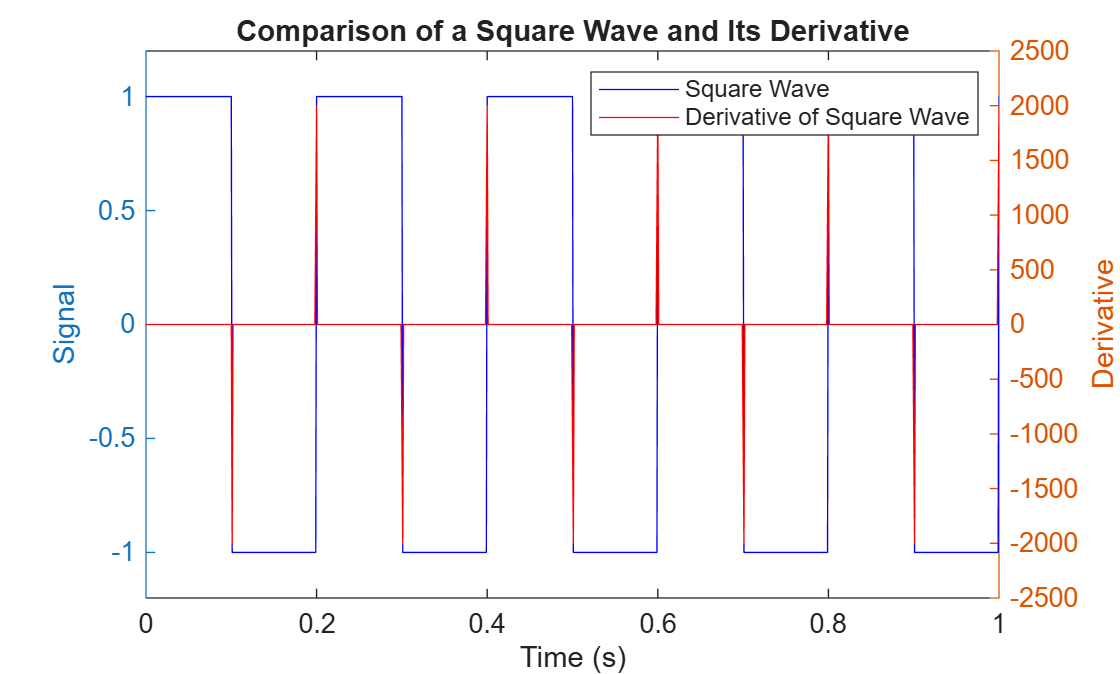

% Defining Parameters
h=0.001;      % Step count (seconds)
a=0;          % Starting time (seconds)
b1=10;         % Ending time for square waves (seconds)
b2=10;        % Ending time for sine waves (seconds)
m1=(b1-a)/h;  % Number of elements for square wave arrays
m2=(b2-a)/h;  % Number of elements for sine wave arrays
t1=a:h:b1;    % Time array with step size of h (0.001) over the 11 second interval
t2=a:h:b2;    % Time array with step size of h (0.001) over the 10 second interval

% Square wave (S1)
S1 = zeros(1, m1+1); % Initializing square wave array

% Creating loop for square wave generation
count = 0;
for i=1:m1+1
    if count <= 100
        S1(i) = 1;
        count = count + 1;
    elseif count < 199
        S1(i) = -1;
        count = count + 1;
    else
        S1(i) = -1;
        count = 0;
    end
end

% Sine wave (S2)
S2 = sin(t2);

% Gaussian noise for square wave
random_data1 = rand(1,m1+1);  % Creating random data
random_data1 = random_data1 - mean(random_data1); % Subtracting mean from random data; this ensures the average of the data is 0 and the noise is centered around 0

% Gaussian noise for sine wave
random_data2 = rand(1,m2+1);  % Creating random data
random_data2 = random_data2 - mean(random_data2); % Subtracting mean from random data; this ensures the average of the data is 0 and the noise is centered around 0

% Creating noisy signals by adding Gaussian noise arrays to respective signals
S_n1 = S1 + 0.05*random_data1;
S_n2 = S2 + 0.05*random_data2;

% Initializing derivative signals (both regular and noisy)
dS1 = zeros(1, m1+1);
dS2 = zeros(1, m2+1);
dS_n1 = zeros(1, m1+1);
dS_n2 = zeros(1, m2+1);

% Setting initial condition for sine signals to be 1
% (The derivative of a square wave starts at 0)
dS2(1) = 1;
dS_n2(1) = 1;

% Computing derivative of square waves (both regular and noisy) 
% using Euler's method (formula in lab manual)
for i=2:m1+1
    dS1(i) = (S1(i) - S1(i-1))/h;
    dS_n1(i) = (S_n1(i) - S_n1(i-1))/h;
end

% Computing derivative of sine waves (both regular and noisy) 
% using Euler's method (formula in lab manual)
for i=2:m2+1
    % Euler's method to solving differential equations
    dS2(i) = (S2(i) - S2(i-1))/h;
    dS_n2(i) = (S_n2(i) - S_n2(i-1))/h;
end

% Plotting regular square wave and its derivative
yyaxis left
plot(t1, S1, 'b')
ylabel('Signal')
ylim([-1.2 1.2])
hold on
yyaxis right
plot(t1, dS1, 'r')
ylabel('Derivative')
ylim([-2500 2500])
legend("Square Wave", "Derivative of Square Wave")
xlabel('Time (s)')
xlim([0 1])
title('Comparison of a Square Wave and Its Derivative')
hold off

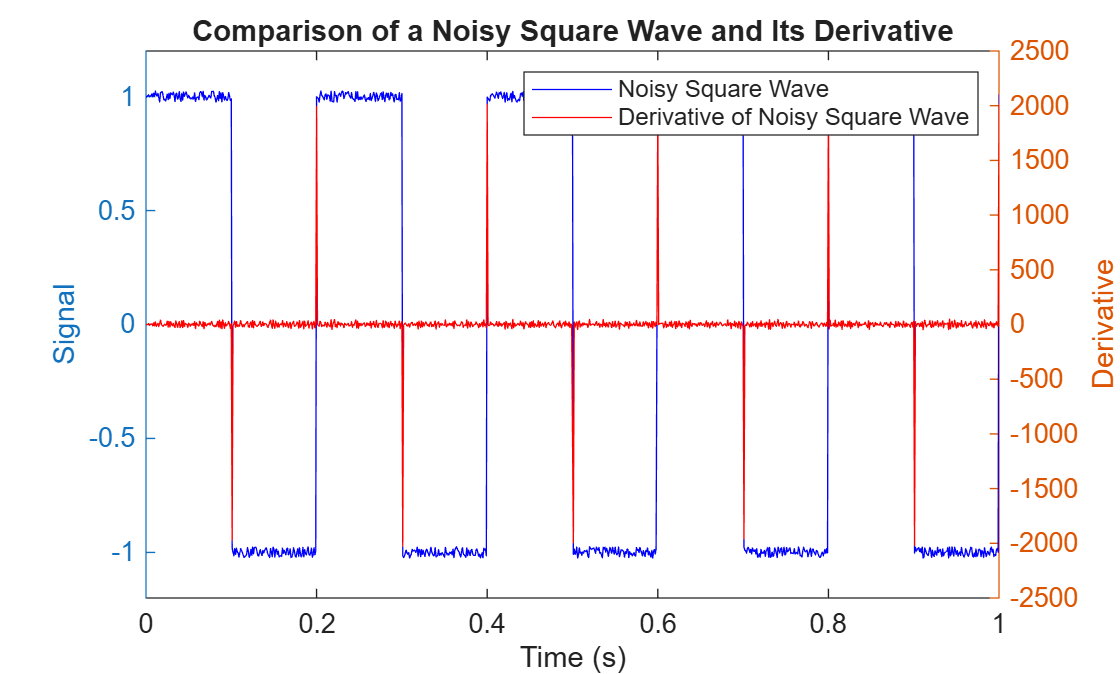

clf;

% Plotting regular sine wave and its derivative
yyaxis left
plot(t1, S_n1, 'b')
ylabel('Signal')
ylim([-1.2 1.2])
hold on
yyaxis right
plot(t1, dS_n1, 'r')
ylabel('Derivative')
ylim([-2500 2500])
legend("Noisy Square Wave", "Derivative of Noisy Square Wave")
xlabel('Time (s)')
xlim([0 1])
title('Comparison of a Noisy Square Wave and Its Derivative')
hold off

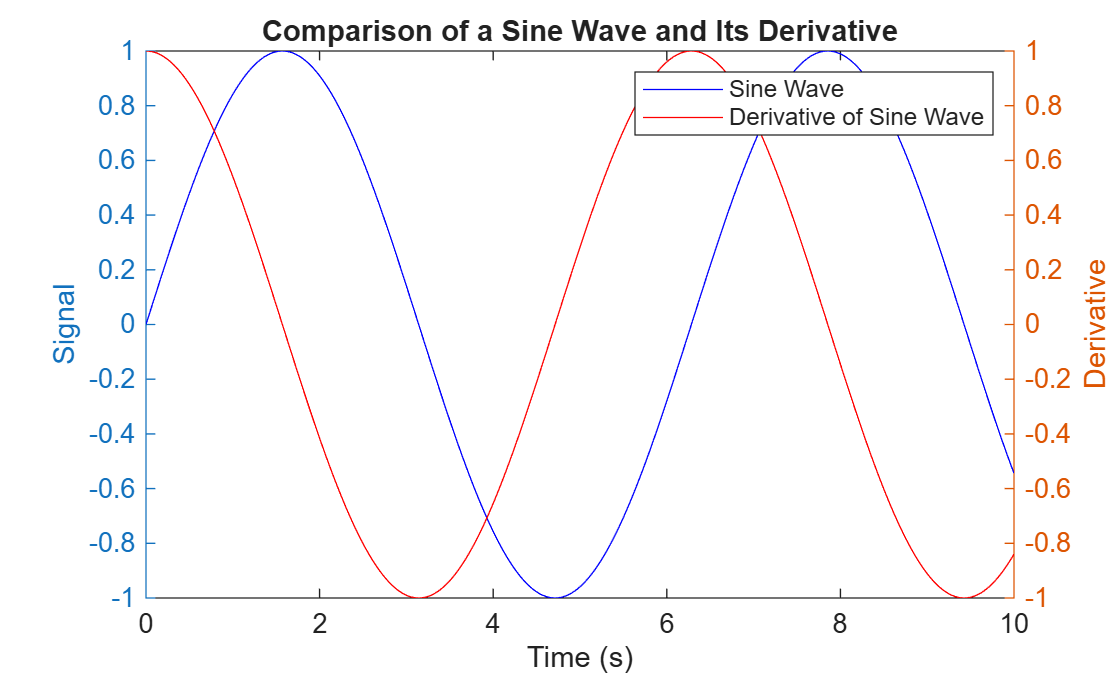

clf;

% Plotting noisy square wave and its derivative
yyaxis left
plot(t2, S2, 'b')
ylabel('Signal')
ylim([-1 1])
hold on
yyaxis right
plot(t2, dS2, 'r')
ylabel('Derivative')
ylim([-1 1])
legend("Sine Wave", "Derivative of Sine Wave")
xlabel('Time (s)')
title('Comparison of a Sine Wave and Its Derivative')
hold off

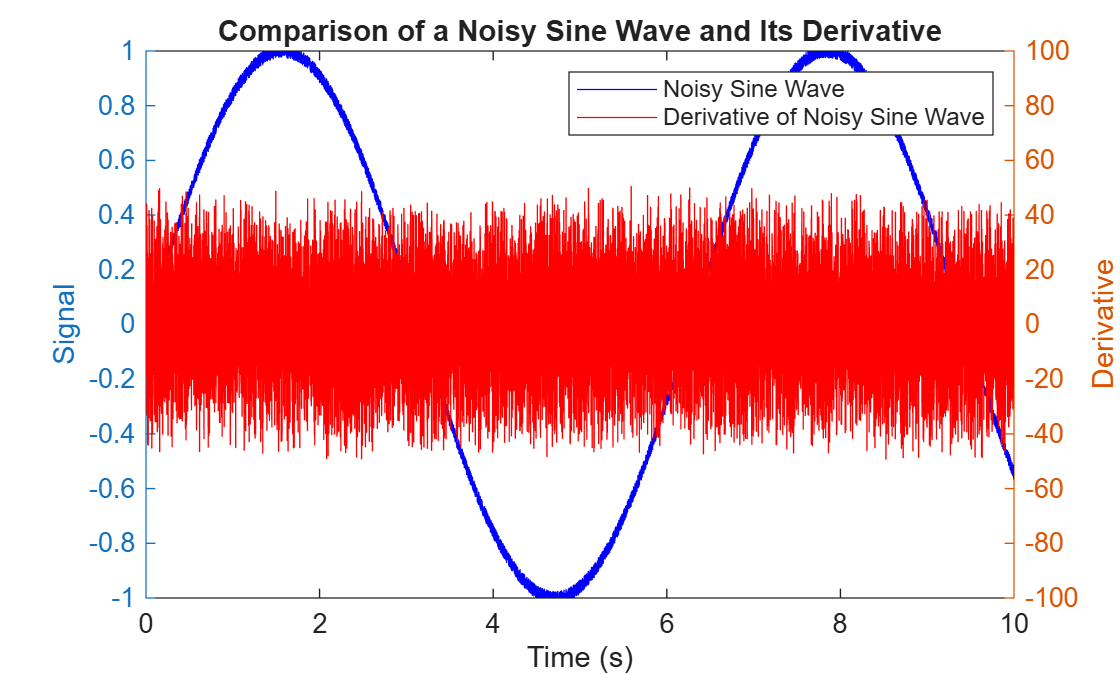

clf;

% Plotting noisy sine wave and its derivative
yyaxis left
plot(t2, S_n2, 'b')
ylabel('Signal')
ylim([-1 1])
hold on
yyaxis right
plot(t2, dS_n2, 'r')
ylabel('Derivative')
ylim([-100 100])
legend("Noisy Sine Wave", "Derivative of Noisy Sine Wave")
xlabel('Time (s)')
title('Comparison of a Noisy Sine Wave and Its Derivative')
hold off;

## Noise Amplification:

From the plots shown, it can be seen that when noise is introduced into a system, the derivative of the signals respond with an amplification of noise. For the square wave, the derivative is 0 everywhere except at the step changes, which gives it a very stable response. For the noisy signal, due to the slight sudden changes of amplitude between time points, the change within that time is not 0, so the derivative function reports values not equal to 0 while the input is "steady". This is even more present with the sine wave function. The regular function has its derivative follow a cosine function, but when noise is introduced, it is almost impossible to determine what the derivative function is supposed to be. Between the two noisy functions, it can be seen that the overall amplitudes of the derivative function lay somewhere between 30-50. The noise signal introduced only had amplitudes up to 0.5, which means by taking the derivative of the noise and the signal, the noise gets amplified quite a bit.

## Effect of Sudden Change:

The effects of sudden change can also be seen from these plots. From the square wave, it can be seen that the only time where the derivative plot is not 0 is when the wave changes from negative to positive (-1 to +1). In our plots, this shows up as a value of 2000, but in an ideal square wave, the derivative at the change would be infinite. This is because the change happens instantaneously, which means the rate of change at that point is also instantaneous. From the sine wave function, the derivative function shows up as a smooth cosine wave. This is because there is no sudden change in the signal, so the derivative block can take the derivative with no issue. However, with noise introduced, the change in signal between two points is now much larger than the regular signal, which impacts the derivative calculation and amplifies the derivative signal.